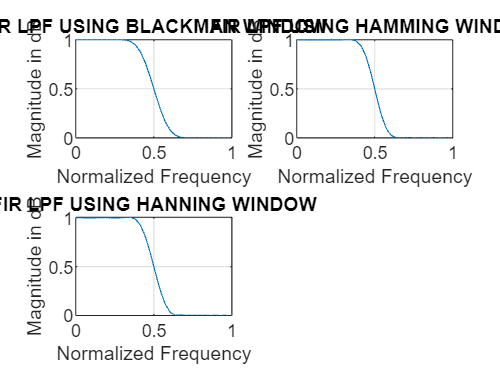

clear all;
close all;
clc;

wc = 0.5 * pi;
N = 25;
w = 0:0.1:pi;

% Generate windows manually
n = 0:N;

blackman_window = 0.42 - 0.5 * cos(2 * pi * n / N) + 0.08 * cos(4 * pi * n / N);
hamming_window = 0.54 - 0.46 * cos(2 * pi * n / N);
hanning_window = 0.5 * (1 - cos(2 * pi * n / N));

% Design low-pass FIR filters
b_blackman = sin(wc * (n - (N / 2))) ./ (pi * (n - (N / 2))) .* blackman_window;
b_hamming = sin(wc * (n - (N / 2))) ./ (pi * (n - (N / 2))) .* hamming_window;
b_hanning = sin(wc * (n - (N / 2))) ./ (pi * (n - (N / 2))) .* hanning_window;

% Compute frequency responses
h_blackman = freqz(b_blackman, 1, w);
h_hamming = freqz(b_hamming, 1, w);
h_hanning = freqz(b_hanning, 1, w);

% Plot the frequency responses
figure;

subplot(2, 2, 1)
plot(w/pi, abs(h_blackman))
grid;
xlabel('Normalized Frequency');
ylabel('Magnitude in dB');
title('FIR LPF USING BLACKMAN WINDOW');

subplot(2, 2, 2)
plot(w/pi, abs(h_hamming))
grid;
xlabel('Normalized Frequency');
ylabel('Magnitude in dB');
title('FIR LPF USING HAMMING WINDOW');

subplot(2, 2, 3)
plot(w/pi, abs(h_hanning))
grid;
xlabel('Normalized Frequency');
ylabel('Magnitude in dB');
title('FIR LPF USING HANNING WINDOW');

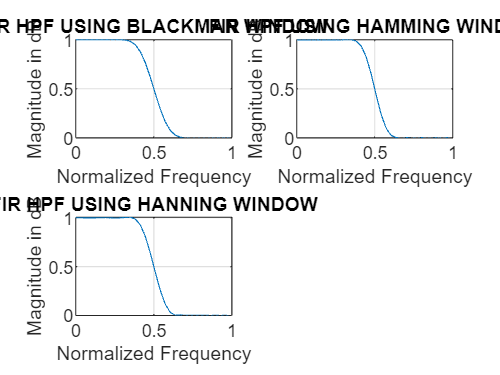

% FIR High Pass without inbuilt
clear all;
close all;
clc;

wc = 0.5 * pi;
N = 25;
w = 0:0.1:pi;

% Generate windows manually
n = 0:N;

blackman_window = 0.42 - 0.5 * cos(2 * pi * n / N) + 0.08 * cos(4 * pi * n / N);
hamming_window = 0.54 - 0.46 * cos(2 * pi * n / N);
hanning_window = 0.5 * (1 - cos(2 * pi * n / N));

% Design high-pass FIR filters
b_blackman = -sin(wc * (n - (N / 2))) ./ (pi * (n - (N / 2))) .* blackman_window;
b_hamming = -sin(wc * (n - (N / 2))) ./ (pi * (n - (N / 2))) .* hamming_window;
b_hanning = -sin(wc * (n - (N / 2))) ./ (pi * (n - (N / 2))) .* hanning_window;

% Compute frequency responses
h_blackman = freqz(b_blackman, 1, w);
h_hamming = freqz(b_hamming, 1, w);
h_hanning = freqz(b_hanning, 1, w);

% Plot the frequency responses
figure;

subplot(2, 2, 1)
plot(w/pi, abs(h_blackman))
grid;
xlabel('Normalized Frequency');
ylabel('Magnitude in dB');
title('FIR HPF USING BLACKMAN WINDOW');

subplot(2, 2, 2)
plot(w/pi, abs(h_hamming))
grid;
xlabel('Normalized Frequency');
ylabel('Magnitude in dB');
title('FIR HPF USING HAMMING WINDOW');

subplot(2, 2, 3)
plot(w/pi, abs(h_hanning))
grid;
xlabel('Normalized Frequency');
ylabel('Magnitude in dB');
title('FIR HPF USING HANNING WINDOW');

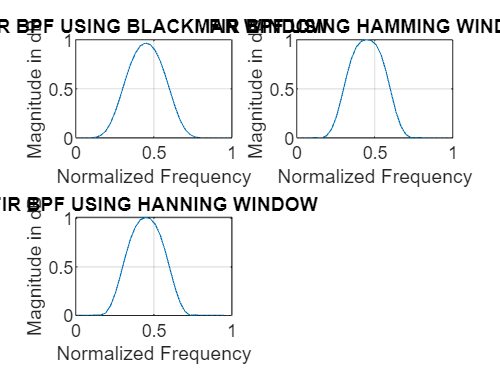




clc; clear all;

wc_low = 0.3 * pi; % Low cutoff frequency
wc_high = 0.6 * pi; % High cutoff frequency
N = 25;
w = 0:0.1:pi;

% Generate windows manually
n = 0:N;

blackman_window = 0.42 - 0.5 * cos(2 * pi * n / N) + 0.08 * cos(4 * pi * n / N);
hamming_window = 0.54 - 0.46 * cos(2 * pi * n / N);
hanning_window = 0.5 * (1 - cos(2 * pi * n / N));

% Design band-pass FIR filters
b_blackman = (sin(wc_high * (n - (N / 2))) - sin(wc_low * (n - (N / 2)))) ./ (pi * (n - (N / 2))) .* blackman_window;
b_hamming = (sin(wc_high * (n - (N / 2))) - sin(wc_low * (n - (N / 2)))) ./ (pi * (n - (N / 2))) .* hamming_window;
b_hanning = (sin(wc_high * (n - (N / 2))) - sin(wc_low * (n - (N / 2)))) ./ (pi * (n - (N / 2))) .* hanning_window;

% Compute frequency responses
h_blackman = freqz(b_blackman, 1, w);
h_hamming = freqz(b_hamming, 1, w);
h_hanning = freqz(b_hanning, 1, w);

% Plot the frequency responses
figure;

subplot(2, 2, 1)
plot(w/pi, abs(h_blackman))
grid;
xlabel('Normalized Frequency');
ylabel('Magnitude in dB');
title('FIR BPF USING BLACKMAN WINDOW');

subplot(2, 2, 2)
plot(w/pi, abs(h_hamming))
grid;
xlabel('Normalized Frequency');
ylabel('Magnitude in dB');
title('FIR BPF USING HAMMING WINDOW');

subplot(2, 2, 3)
plot(w/pi, abs(h_hanning))
grid;
xlabel('Normalized Frequency');
ylabel('Magnitude in dB');
title('FIR BPF USING HANNING WINDOW');